# Simulink/ Simscape Batteriemodelle

In diesem Livescript soll ein Batterimodell über Simulink und Simscape erstellt und die Unterschiede betrachtet werden.

## Batterie

Im folgenden werden die Randbedingungen der Batterie festgelegt

%t = 0:1e-6:10;
%sim('Batteriemodelle_vergleich',t);
U_b0 = 12;
R_i = 20e-3;

## Gleichstrommotor

Geben Sie nun die Daten für den Gleichstrommotor ein

R_a = 3.98;
L = 2.3*0.001;
c_Mo = 0.027;
J_T = 3.3*10^-6; 
M_l = -0.03;
% Parameter setzen für Simulink 
U_gen = 0;
R_v = 0;
switch_12 = 0;
switch_48 = 0;
switch_gen = 0;
U_k = 0;

## Simulink/ Simscape Vergleich

Im folgenden Bild sind die jeweiligen Modelle desselben Gleichstrommotors in Simunlink und Simscape aufgeführt. In Simulink wird dieser durch ein Blockschaltbild dargestellt, hier muss der Benutzer die Glieder selber mit den richtigen Rechenoperatoren verbinden. Nutzt man zur Simulation Simscape, so kann man fertige Bauteile miteinander verknüpfen und eine Art Ersatzschaltbild erstellen. Aus diesem kann man über den Einbau verschiedener Sensoren, die physikalischen Werte auslesen

sim('Batteriemodelle_vergleich');
%figure
%snapshotModel('Batteriemodelle_vergleich')

### Drehzahl

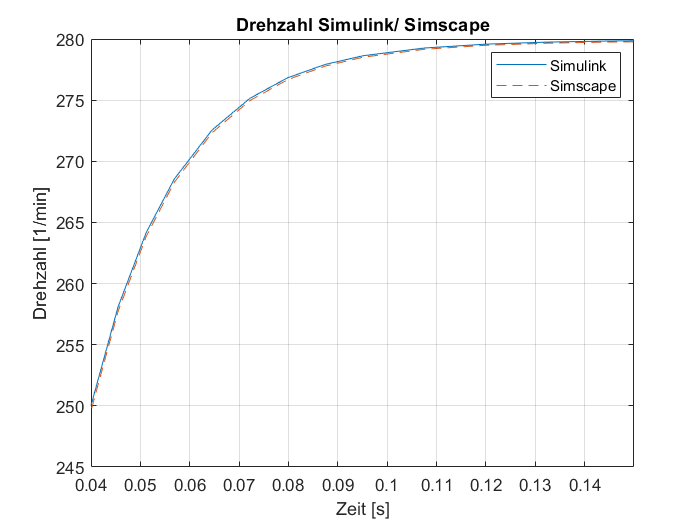

figure
plot(ans.w_Simulink)
hold on
grid on
plot(ans.w_Simscape, '--')
xlim([0.04 0.15])
%ylim([400 450]) 
title('Drehzahl Simulink/ Simscape')
xlabel('Zeit [s]')                  %X-Achsenbeschriftung
ylabel('Drehzahl [1/min]')          %Y-Achsenbeschriftung
legend('Simulink','Simscape')

### Klemmenspannung

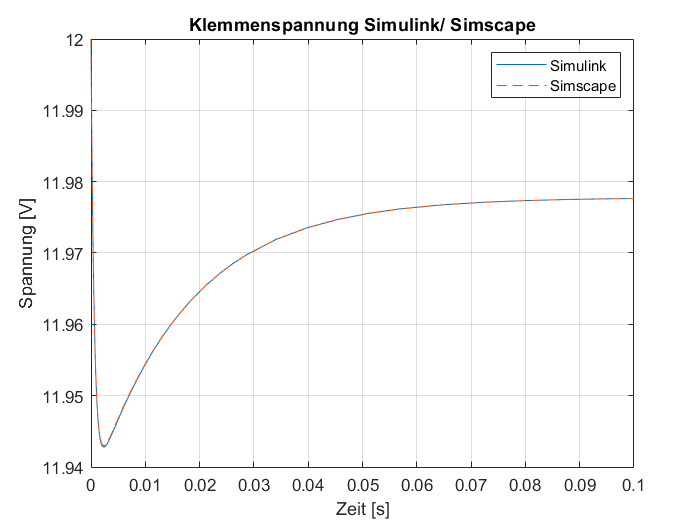

figure
plot(ans.U_Simulink)
hold on
grid on
plot(ans.U_Simscape, '--')
xlim([0.0 0.1])
%ylim([10.0 14.0]) 
title('Klemmenspannung Simulink/ Simscape')
xlabel('Zeit [s]')              %X-Achsenbeschriftung
ylabel('Spannung [V]')          %Y-Achsenbeschriftung
legend('Simulink','Simscape')

## Verbraucher

Die Verbraucherrechnungen werden nun nur noch mit Simscape weitergerechnet

Falls im Kapitel ***Batterie ***eine *Batteriespannung* von *48V* gewählt wurde, so wird für die folgenden Verbraucher ein DC-DC Wandler benötigt.

%Verbraucher können aktiviert/ deaktiviert werden. 
%Sind diese aktiv, wird festgestellt, welche Bordnetzspannung anliegt
% und welcher Schalter geschlossen werden muss (12V/ 48V System)
Verbraucher = true;
fprintf('------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------

if Verbraucher == 1
switch Verbraucher
    case 0
        switch_12 = 0;
        switch_48 = 0;
    case 1
        if U_b0 == 12
            switch_12 = 1;
            switch_48 = 0;
        else
            switch_48 = 1;
            switch_12 = 0;
        end
end
Mototronik = false;
if Mototronik == 1
    fprintf('Die Mototronik benötigt eine mittlere Leistung von 200W') 
    V_mototronik = 200;
else
    V_mototronik = 0;
end
Kraftstoffpumpe = false;
if Kraftstoffpumpe == 1
    fprintf('Die Kraftstoffpumpe benötigt eine mittlere Leistung von 50W')
    V_kraftstoffpumpe = 50;
else
    V_kraftstoffpumpe = 0;
end
Abblendlicht = false;
if Abblendlicht==1
    fprintf('Das Abblendlicht benötigt eine mittlere Leistung von 90W') 
      V_abblendlicht = 90;
else
    V_abblendlicht = 0;
end
Heizung = false;
if Heizung==1
    fprintf('Die Heizung benötigt eine mittlere Leistung von 60W') 
      V_heizung = 60;
else
    V_heizung = 0;
end
%P_ges = V_mototronik + V_kraftstoffpumpe + V_abblendlicht + V_heizung;   %Berechnung der gesamten Verbraucherleistung
P_ges = 500
R_v = 144/P_ges;     %Berechnung des Ersatzwiderstands
fprintf('------------------------------------------------------------------------------------------')
fprintf('Die gesamte Verbraucherleistung beträgt %4.2f W', P_ges)
fprintf('Daraus ergibt sich ein Verbraucherwiderstand von %4.2f Ω', R_v)
else
end

P_ges = 500

------------------------------------------------------------------------------------------

Die gesamte Verbraucherleistung beträgt 500.00 W

Daraus ergibt sich ein Verbraucherwiderstand von 0.29 Ω

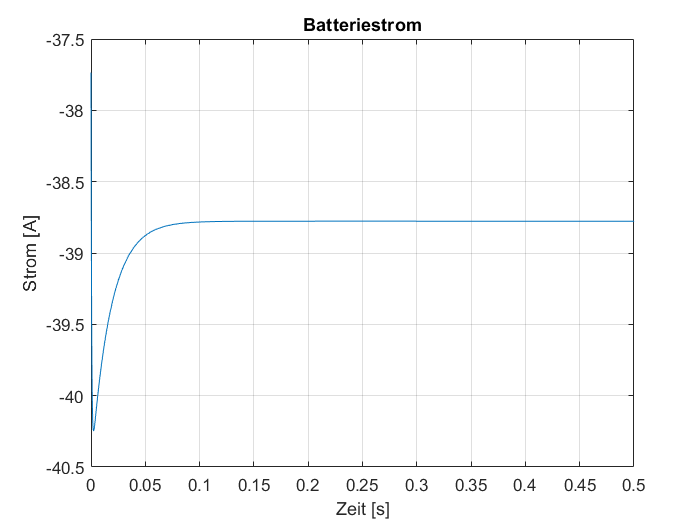

sim('Batteriemodelle_vergleich');
figure
plot(ans.I_SimBat)
grid on
xlim([0.0 0.5])
title('Batteriestrom')
xlabel('Zeit [s]')              %X-Achsenbeschriftung
ylabel('Strom [A]')          %Y-Achsenbeschriftung

fprintf('Ein negativer Batteriestrom bedeutet, dass diese entladen wird. Bei einem positiven Strom wird sie geladen.')

Ein negativer Batteriestrom bedeutet, dass diese entladen wird. Bei einem positiven Strom wird sie geladen.

## Generator

Im folgenden wir der Generator vereinfacht als *Spannungsquelle* dargestellt.

In der Livescript_Bibliothek kann das Modell 'Generator' aufgerufen werden, in dem der Generator im detail dargestellt wird.

i_length = length(ans.U_b.signals.values);
U_k = ans.U_b.signals.values(i_length);
fprintf('Die Klemmenspannung beträgt %4.2f V', U_k)

Die Klemmenspannung beträgt 11.22 V

fprintf('------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------

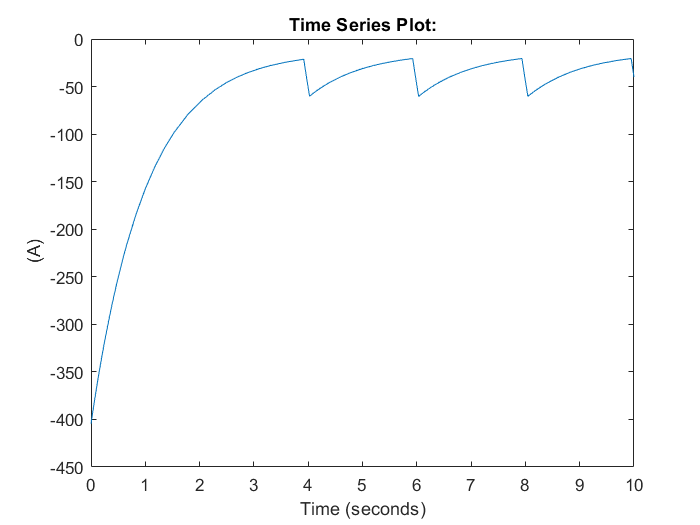

switch U_b0
    case 12
        u_step1 = 11;
        u_step2 = 10;
    case 48
        u_step1 = 45;
        u_step2 = 40;
end
U_step2 = U_b0 +2;
if U_k < u_step1 
   fprintf('Oh nein! Die Klemmenspannung ist unter %4.2f V gefallen, um die Verbraucher weiterhin mit der gewünschten Spannung von 12V zu versorgen,', u_step1 )
   fprintf('versorgt der Generator das Bordnetz nun zusätzlich mit %4.2f V', U_b0)
   fprintf('Durch setzten des Hakens "Generator" kann dieser aktiviert werden. Beobachten sie die Änderungen der Klemmenspannunng und des Batteriestroms')
elseif U_k < u_step2
    fprintf('Oh nein! Die Klemmenspannung ist unter %4.2f V gefallen, der Generator unterstützt nun nichtmehr nur das Bordnetz', u_step2)
    fprintf('sondern lädt auch die Batterie. Daher speist er das Bordnetz mit %4.2f V', U_step2)
    fprintf('Durch setzten des Hakens "Generator" kann dieser aktiviert werden. Beobachten sie die Änderungen der Klemmenspannunng und des Batteriestroms')
end   
Generator = true;
if Generator == 1
if U_k < 12
    switch_gen = 1;
end
sim('Batteriemodelle_vergleich');
figure 
plot(ans.I_SimBat)
end